load('TTC data files/B1654run35.mat')

Group data:

length=size(ET);
scalefactor=0.6;
[loadlb,loadub]=groupdata(FZ(1:4140),5,100,0);

Fit Pacejka function to data:


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


ans =     '
     Local minimum possible.
     
     lsqcurvefit stopped because the final change in the sum of squares relative to 
     its initial value is less than the value of the function tolerance.
     
     <stopping criteria details>
     
     Optimization stopped because the relative sum of squares (r) is changing
     by less than options.FunctionTolerance = 1.000000e-06.
     
     '


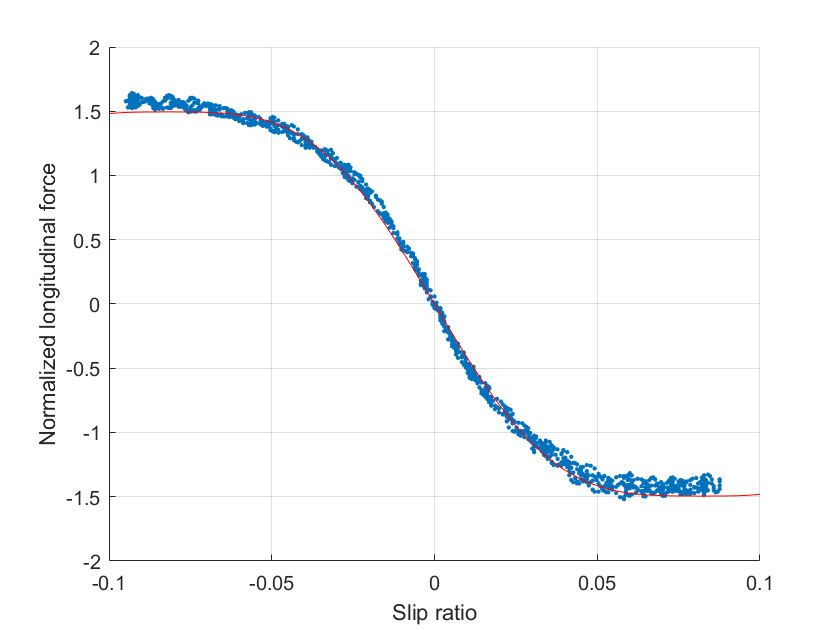

ans =    -0.8214  -34.4817   -1.4950  220.2593


%for i=1:size(loadlb,1)
%    start = 0;
%    if (i>1)
%        start=loadub(i-1);
%    end
%    [SLlb,SLub]=groupdata(SL(loadlb(i):loadub(i)),3,0.19,start);
%    fit([SL(SLlb(1):SLub(1));SL(SLlb(3):SLub(3))],[NFX(SLlb(1):SLub(1));NFX(SLlb(3):SLub(3))]); % Increasing SA
%    fit(SL(SLlb(2):SLub(2)),NFX(SLlb(2):SLub(2)));
%end
C=zeros(12,4);
%[SLlb,SLub]=groupdata(SL(loadlb(1):loadub(1)),3,0.19,0)
%C(2,:) = fit(SL(SLlb(2):SLub(2)),NFX(SLlb(2):SLub(2)));
fit(SL(loadlb(1):loadub(1)),NFX(loadlb(1):loadub(1)))

save('pacejka_coefficients_longitudinal.mat',"C");

Define Pacejka function:

function y = pacejka(C,x)
y=C(3)*sin(C(2)*atan(C(1)*(1-C(4))*x+C(4)*atan(C(1)*x)));
end

Fit curve for a single vertical load group:

function C = fit(xdata,ydata)
hold off
scalefactor=0.6;
xdata=xdata*scalefactor;
ydata=ydata*scalefactor;
ydata=ydata*2.505/2.83; % Compensate for different tire
scatter(xdata,ydata,5,'filled')
hold on
lb=-inf*ones(4,1);
ub=inf*ones(4,1);
C0=[-0.03,-100,-1.6,-50];
options=optimoptions('lsqcurvefit');
options.MaxFunctionEvaluations=6000;
options.MaxIterations=6000;
options.Algorithm='levenberg-marquardt';
[Cfinal,~,~,~,output] = lsqcurvefit(@(C,x) pacejka(C,x),C0,xdata,ydata,lb,ub,options);
output.message
x=linspace(-0.1,0.1);
plot(x,pacejka(Cfinal,x),'red')
xlabel('Slip ratio')
ylabel('Normalized longitudinal force')
grid on
hold off
C=Cfinal;
end

Grouping data:

function [lb,ub] = groupdata(data,n,range,start)
    lb=zeros(n,1);
    ub=zeros(n,1);
    lb(1)=1;
    x = 0;
    for i=1:n
        if i>1
            lb(i)=ub(i-1)+1;
        end
        while 1
            x=x+1;
            if (x >= size(data,1)) || (abs(data(x) - data(x+1)) > range)
                ub(i)=x;
                break
            end
        end
    end
    lb=lb+start*ones(n,1);
    ub=ub+start*ones(n,1);
end
